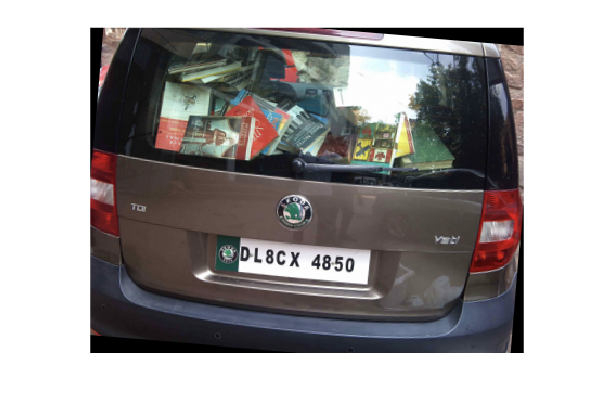

clear all; close all;
f = imread("car_images/Good_img/working/Cars3.png");
f = imrotate(f, -5, "bilinear", "crop");
imshow(f)

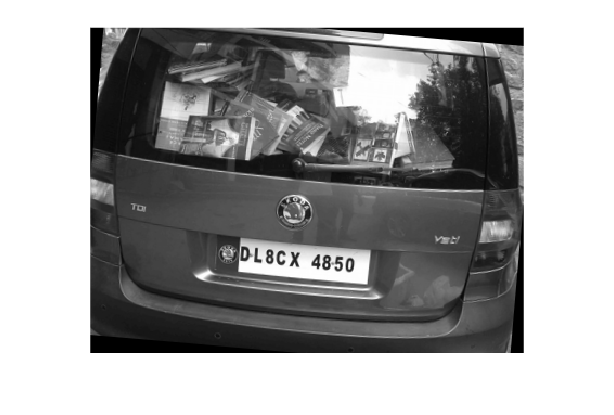

f2 = rgb2gray(f);
imshow(f2)

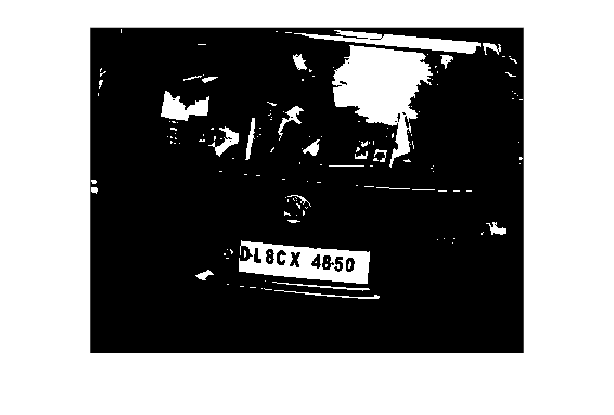

%Binarize image and isolate the license plate
f3 = imadjust(f2, [0.5 1], [0 1]);
f3 = imbinarize(f3);
f3 = imclearborder(f3);
imshow(f3)

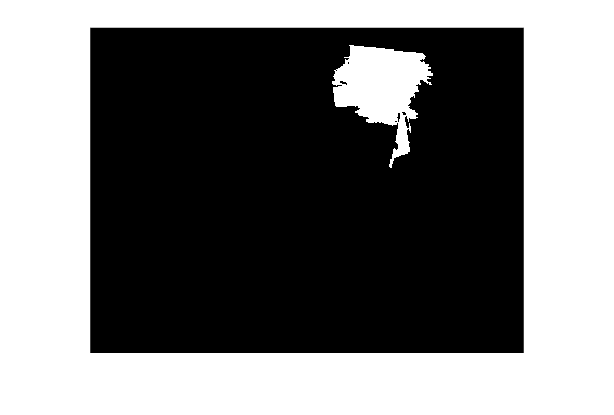

CC = bwconncomp(f3);
numPixels = cellfun(@numel, CC.PixelIdxList);
[biggest, idx] = max(numPixels);
for k = 1:length(numPixels)
    if k ~= idx
        f3(CC.PixelIdxList{k}) = 0;
    end
end
imshow(f3)

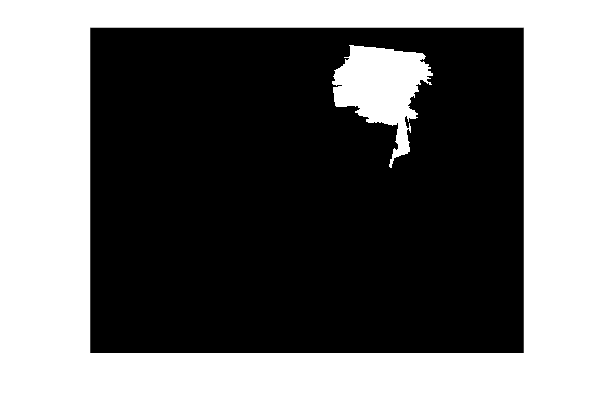

%Hide the letters to get better corner detection
f4 = imfill(f3, "holes");

f5 = f4;

imshow(f5)

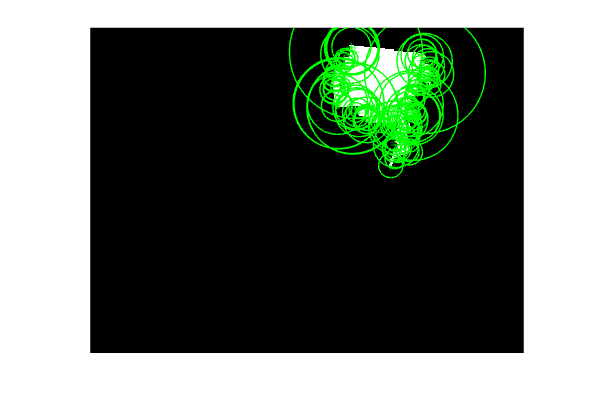

%Detect the 4 corners of the license plate
points = detectBRISKFeatures(f5);
figure(1); imshow(f5);
hold on;
plot(points.selectStrongest(100));

mainpoints = points.selectStrongest(100).Location;


[toppoint, topidx] = min(mainpoints(:,2));
[bottompoint, bottomidx] = max(mainpoints(:,2));
[leftpoint, leftidx] = min(mainpoints(:,1));
[rightpoint, rightidx] = max(mainpoints(:,1));

fourcorners = [mainpoints(topidx,:); mainpoints(rightidx,:); mainpoints(bottomidx,:); mainpoints(leftidx,:)]

fourcorners = 4×2 single matrix
  241.4407   18.1832
  315.7500   43.3750
  277.7994  127.4720
  224.5000   50.5000


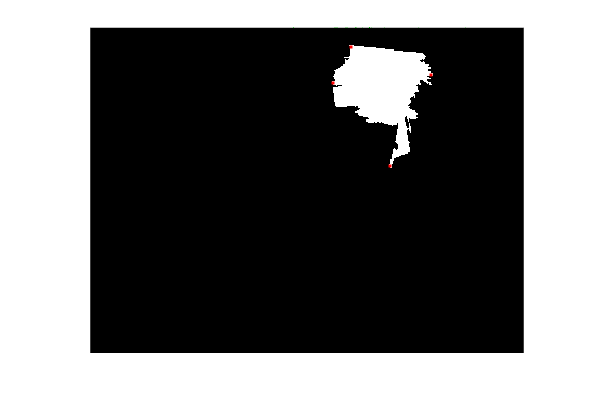


rowSums = sum(fourcorners,2);
% Sort the sums, obtaining the sorted indices
[~, sortedIndices] = sort(rowSums);
% Use the indices to reorder the matrix rows
sortedcorners = fourcorners(sortedIndices, :);

figure(2); imshow(f5);
hold on;
plot(sortedcorners(:,1),sortedcorners(:,2),'r.');

xi = sortedcorners(:,1);
yi = sortedcorners(:,2);

% Define the base points for the transformation
base = [1 1; 1 size(f2, 1); size(f2, 2) 1; size(f2, 2) size(f2, 1)]

base =      1     1
     1   300
   400     1
   400   300



% Compute the homography transform
tf = fitgeotrans([xi, yi], base, 'projective');
H = tf.T;

% Perform the homography transformation
[xf, xf_ref] = imwarp(f2, tf);

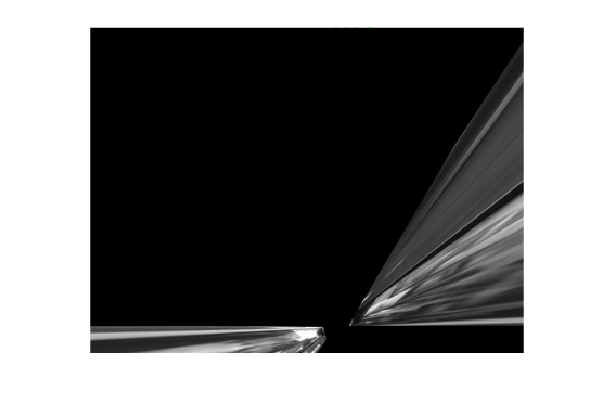


% Specify the desired width and height of the output image (in pixels)
desired_width = size(f2, 2);
desired_height = size(f2, 1);

% Resize the output image while maintaining its aspect ratio
xf_resized = imresize(xf, [desired_height, desired_width]);

% Display the resized transformed image
figure (3); imshow(xf_resized)